# **RS-WISP-06-04: Combined Simulation Example**

**WorkerInSpace**

**Hongseok Kim**

clear;clc;
addpath('C:\Users\user\Desktop\Redstone_WISP\RS_WISP_05_RPOD_Functions')

## I. Mission Sequence

## II. Satellite Orbit Initialization

%% Input Parameters
% https://www.space-track.org/basicspacedata/query/class/gp/NORAD_CAT_ID/58400/format/xml/emptyresult/show


%Initial Epoch Definition
Year = 2025;
Month = 2;
Day = 16;
Hour = 22;
Minute = 17;
Seconds = 37.053312;

% Target Information
Target.a = 6880.693;
Target.e = 0.00062680;
Target.i = 97.3728;
Target.RAAN = 296.3138;
Target.AOP = 65.9108;
Target.TA = 294.2783;

% Chaser Information
Chaser.a = 6880;
Chaser.e = 0.00062680;
Chaser.i = 97.3728;
Chaser.RAAN = 296;
Chaser.AOP = 65.9108;
Chaser.TA = 294;

% Initialize target and chaser rv data matrix
r_eci_target_data = [];
v_eci_target_data = [];

r_eci_chaser_data = [];
v_eci_chaser_data = [];

r_eci_mothership_data = [];
v_eci_mothership_data = [];

time_vector_data = [];

### III. Mission Sequence

%% Main Algorithm
% Change to ECI frame

% rv data of the target wrt ECI
[r_target, v_target] = kepler2ijk_hs(Target.a, Target.e, Target.i, Target.RAAN, Target.AOP, Target.TA);

% rc data of the chaser wrt ECI
[r_chaser, v_chaser] = kepler2ijk_hs(Chaser.a, Chaser.e, Chaser.i, Chaser.RAAN, Chaser.AOP, Chaser.TA);

r_eci_mothership = r_chaser;
v_eci_mothership = v_chaser;

### III.1 Sequence 1: Two-Impulse Rendezvous toward target

#### 3.1.1 Algorithm for finding optimal delta_t

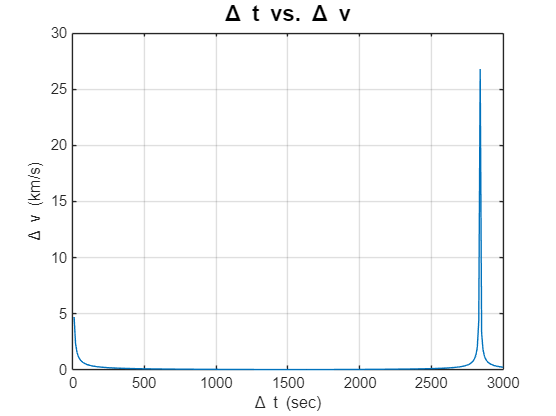

time_of_travel_vec  = 10:10:3000;
Delta_v_info_vec = zeros(length(time_of_travel_vec),1);

for i = 1:length(time_of_travel_vec)
 [Delta_v_0, Delta_v_f, delta_r_t_mat, delta_v_t_mat, v_plus_ECI, t_vector] = two_impulse_rendezvous(r_target, v_target, r_chaser, v_chaser, time_of_travel_vec(i));
 Delta_v_info_vec(i) = norm(Delta_v_0);
end

figure;
plot(time_of_travel_vec, Delta_v_info_vec)
title('\Delta t vs. \Delta v','FontSize',15,'FontWeight','bold')
xlabel('\Delta t (sec)')
ylabel('\Delta v (km/s)')
grid on


minimum_Delta_v = min(Delta_v_info_vec);
optimized_delta_t_index = find(Delta_v_info_vec == minimum_Delta_v);
selected_t_f = time_of_travel_vec(optimized_delta_t_index);

#### 3.1.2 Get Delta_v by running the function

% Timing of Docking
t_f = selected_t_f;
[Delta_v_0, Delta_v_f, delta_r_t_mat, delta_v_t_mat, v_plus_ECI, t_vector] = two_impulse_rendezvous(r_target, v_target, r_chaser, v_chaser, t_f);

norm(Delta_v_0)

ans = 0.0194

### 3.1.3 Propagate in ECI Frame for delta_t

% Propagate Target and Chaser under 2-body dynamics
[t_1,y_chaser] = orbit_propagation(r_chaser, v_plus_ECI, t_vector);
[t,y_target] = orbit_propagation(r_target, v_target, t_vector);
[t,y_mothership] = orbit_propagation(r_eci_mothership,v_eci_mothership,t_vector);

% Save the Propagated Data
r_eci_chaser_data = [r_eci_chaser_data; y_chaser(:,1:3)];
v_eci_chaser_data = [v_eci_chaser_data; y_chaser(:,4:6)];
r_eci_target_data = [r_eci_target_data; y_target(:,1:3)];
v_eci_target_data = [v_eci_target_data; y_target(:,4:6)];
r_eci_mothership_data = [r_eci_mothership_data; y_mothership(:,1:3)];
v_eci_mothership_data = [v_eci_mothership_data; y_mothership(:,4:6)];
time_vector_data = [time_vector_data;t];

### III.2 Sequence 2: Circumnavigation toward target

#### III.2.2 Get Delta_v by running the function

% Number of Rotation
N = 5;
% Value of Alpha
alpha = 0;

r_target = r_eci_target_data(end,:)';
v_target = v_eci_target_data(end,:)';
r_chaser = r_eci_chaser_data(end,:)';
v_chaser = v_eci_target_data(end,:)';
r_eci_mothership = r_eci_mothership_data(end,:)';
v_eci_mothership = v_eci_mothership_data(end,:)';
time_saved = time_vector_data(end);

[Delta_v_0, delta_r_t_mat, delta_v_t_mat, v_plus_ECI, tf, t_vector] = cirumNavigation(r_target, v_target, r_chaser, v_chaser, N, alpha);

% Propagate Target and Chaser under 2-body dynamics
[t_2,y_chaser] = orbit_propagation(r_chaser, v_plus_ECI, t_vector);
[t,y_target] = orbit_propagation(r_target, v_target, t_vector);
[t,y_mothership] = orbit_propagation(r_eci_mothership,v_eci_mothership,t_vector);

% Save the Propagated Data
r_eci_chaser_data = [r_eci_chaser_data; y_chaser(:,1:3)];
v_eci_chaser_data = [v_eci_chaser_data; y_chaser(:,4:6)];
r_eci_target_data = [r_eci_target_data; y_target(:,1:3)];
v_eci_target_data = [v_eci_target_data; y_target(:,4:6)];
r_eci_mothership_data = [r_eci_mothership_data; y_mothership(:,1:3)];
v_eci_mothership_data = [v_eci_mothership_data; y_mothership(:,4:6)];

time_vector_added = t + time_saved;
time_vector_data = [time_vector_data;time_vector_added];

### III.3 Sequence 3: Return from Target to Chaser

#### 3.3.1 Algorithm for finding optimal delta_t

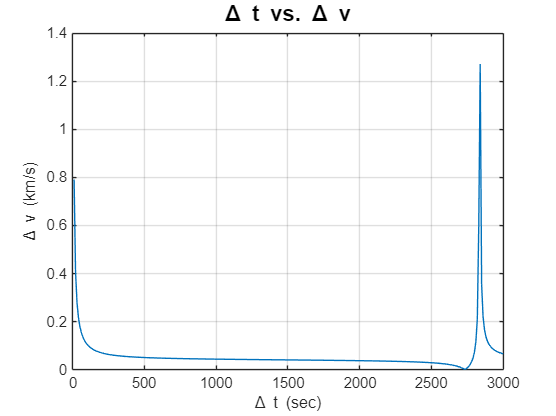

r_chaser = r_eci_chaser_data(end,:)';
v_chaser = v_eci_chaser_data(end,:)';
r_target = r_eci_target_data(end,:)';
v_target = v_eci_target_data(end,:)';
r_eci_mothership = r_eci_mothership_data(end,:)';
v_eci_mothership = v_eci_mothership_data(end,:)';

time_of_travel_vec  = 10:10:3000;
Delta_v_info_vec = zeros(length(time_of_travel_vec),1);


for i = 1:length(time_of_travel_vec)
 [Delta_v_0, Delta_v_f, delta_r_t_mat, delta_v_t_mat, v_plus_ECI, t_vector] = two_impulse_rendezvous(r_eci_mothership, v_eci_mothership, r_chaser, v_chaser, time_of_travel_vec(i));
 Delta_v_info_vec(i) = norm(Delta_v_0);
end

figure;
plot(time_of_travel_vec, Delta_v_info_vec)
title('\Delta t vs. \Delta v','FontSize',15,'FontWeight','bold')
xlabel('\Delta t (sec)')
ylabel('\Delta v (km/s)')
grid on


minimum_Delta_v = min(Delta_v_info_vec);
optimized_delta_t_index = find(Delta_v_info_vec == minimum_Delta_v);
selected_t_f = time_of_travel_vec(optimized_delta_t_index);

#### 3.3.2 Get Delta_v by running the function

% Timing of Docking
t_f = selected_t_f;
[Delta_v_0, Delta_v_f, delta_r_t_mat, delta_v_t_mat, v_plus_ECI, t_vector] = two_impulse_rendezvous(r_eci_mothership, v_eci_mothership, r_chaser, v_chaser, t_f);

norm(Delta_v_0)

ans = 0.0030

#### 3.3.3 Propagate in ECI Frame for delta_t

% Propagate Target and Chaser under 2-body dynamics
[t_1,y_chaser] = orbit_propagation(r_chaser, v_plus_ECI, t_vector);
[t,y_target] = orbit_propagation(r_target, v_target, t_vector);
[t,y_mothership] = orbit_propagation(r_eci_mothership,v_eci_mothership,t_vector);

% Save the Propagated Data
r_eci_chaser_data = [r_eci_chaser_data; y_chaser(:,1:3)];
v_eci_chaser_data = [v_eci_chaser_data; y_chaser(:,4:6)];
r_eci_target_data = [r_eci_target_data; y_target(:,1:3)];
v_eci_target_data = [v_eci_target_data; y_target(:,4:6)];
r_eci_mothership_data = [r_eci_mothership_data; y_mothership(:,1:3)];
v_eci_mothership_data = [v_eci_mothership_data; y_mothership(:,4:6)];

time_vector_added = t + time_saved;
time_vector_data = [time_vector_data;time_vector_added];

#### 3.3.4 Display Stacked Data wrt LVLH of Mothership

delta_r_chaser_LVLH_mat = zeros(length(r_eci_chaser_data(:,1)),3);
delta_r_target_LVLH_mat = zeros(length(r_eci_chaser_data(:,1)),3);

% Change ECI to LVLH wrt Mothership
for i = 1:length(r_eci_chaser_data(:,1))
  r_eci_mothership = r_eci_mothership_data(i,:)';
  v_eci_mothership = v_eci_mothership_data(i,:)';
  r_eci_chaser = r_eci_chaser_data(i,:)';
  r_eci_target = r_eci_target_data(i,:)';

  delta_r_chaser_eci = (r_eci_chaser - r_eci_mothership);
  delta_r_chaser_LVLH = eci2lvlh(delta_r_chaser_eci, r_eci_mothership, v_eci_mothership);
  delta_r_chaser_LVLH_mat(i,:) = delta_r_chaser_LVLH';

  delta_r_target_eci = (r_eci_target - r_eci_mothership);
  delta_r_target_LVLH = eci2lvlh(delta_r_target_eci, r_eci_mothership, v_eci_mothership);
  delta_r_target_LVLH_mat(i,:) = delta_r_target_LVLH';

end

### 3.3.5 Display Stacked Data wrt LVLH of Target

delta_r_chaser_LVLH_target_mat = zeros(length(time_vector_data),3);
delta_r_mothership_LVLH_target_mat = zeros(length(time_vector_data),3);

% Change ECI to LVLH wrt Mothership
for i = 1:length(time_vector_data)

  r_eci_target = r_eci_target_data(i,:)';
  v_eci_target = v_eci_target_data(i,:)';
  r_eci_chaser = r_eci_chaser_data(i,:)';
  r_eci_mothership = r_eci_mothership_data(i,:)';

  delta_r_chaser_eci = (r_eci_chaser - r_eci_target);
  delta_r_chaser_LVLH_target = eci2lvlh(delta_r_chaser_eci, r_eci_target, v_eci_target);
  delta_r_chaser_LVLH_target_mat(i,:) = delta_r_chaser_LVLH_target';

  delta_r_mothership_eci = r_eci_mothership - r_eci_target;
  delta_r_mothership_LVLH_target = eci2lvlh(delta_r_mothership_eci, r_eci_target, v_eci_target);
  delta_r_mothership_LVLH_target_mat(i,:) = delta_r_mothership_LVLH_target';

end

### IV.1 Data Display

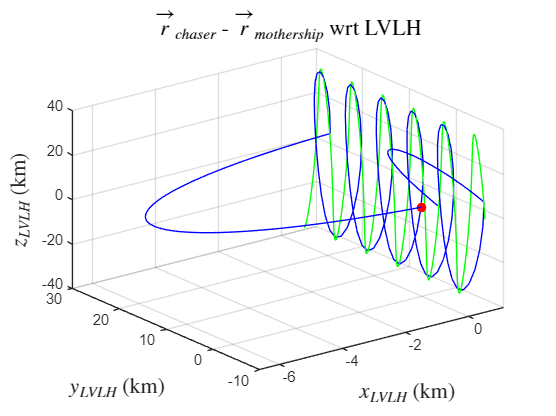

figure;
hold on
plot3(delta_r_chaser_LVLH_mat(:,1),delta_r_chaser_LVLH_mat(:,2),delta_r_chaser_LVLH_mat(:,3),'Color','b')
plot3(delta_r_target_LVLH_mat(:,1),delta_r_target_LVLH_mat(:,2),delta_r_target_LVLH_mat(:,3),'Color','g')
scatter3(0,0,0,'filled',MarkerEdgeColor='r',MarkerFaceColor='r')

% scatter3(delta_r_LVLH_mat(1,1),delta_r_LVLH_mat(1,2),delta_r_LVLH_mat(1,3),'filled',MarkerEdgeColor='g',MarkerFaceColor='g')
% scatter3(delta_r_LVLH_mat(end,1),delta_r_LVLH_mat(end,2),delta_r_LVLH_mat(end,3),'filled',MarkerEdgeColor='b',MarkerFaceColor='b')
hold off
grid on
title('$\vec r_{chaser}$ - $\vec r_{mothership}$ wrt LVLH', 'Interpreter', 'latex','FontSize',15)
xlabel('$x_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
ylabel('$y_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
zlabel('$z_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
% legend('Relative Trajectory','Target Origin','Chaser Starting','Chaser Ending','Location','southoutside')
view(3);

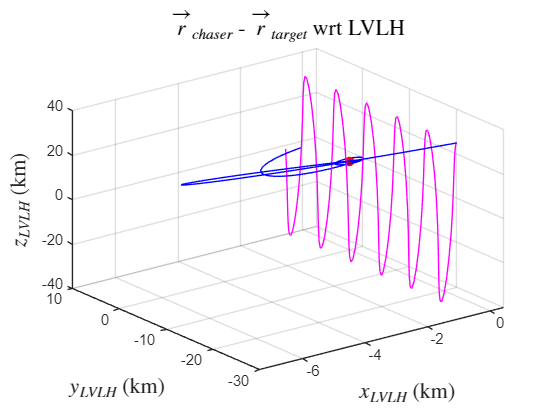



figure;
hold on
plot3(delta_r_chaser_LVLH_target_mat(:,1),delta_r_chaser_LVLH_target_mat(:,2),delta_r_chaser_LVLH_target_mat(:,3),'Color','b')
plot3(delta_r_mothership_LVLH_target_mat(:,1),delta_r_mothership_LVLH_target_mat(:,2),delta_r_mothership_LVLH_target_mat(:,3),'Color','m')
scatter3(0,0,0,'filled',MarkerEdgeColor='r',MarkerFaceColor='r')

% scatter3(delta_r_LVLH_mat(1,1),delta_r_LVLH_mat(1,2),delta_r_LVLH_mat(1,3),'filled',MarkerEdgeColor='g',MarkerFaceColor='g')
% scatter3(delta_r_LVLH_mat(end,1),delta_r_LVLH_mat(end,2),delta_r_LVLH_mat(end,3),'filled',MarkerEdgeColor='b',MarkerFaceColor='b')
hold off
grid on
title('$\vec r_{chaser}$ - $\vec r_{target}$ wrt LVLH', 'Interpreter', 'latex','FontSize',15)
xlabel('$x_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
ylabel('$y_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
zlabel('$z_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
% legend('Relative Trajectory','Target Origin','Chaser Starting','Chaser Ending','Location','southoutside')
view(3);